%load images and labels
crop_size = 64;

[test, train, test_labels, train_labels, test_names, train_names] = load_images(crop_size);

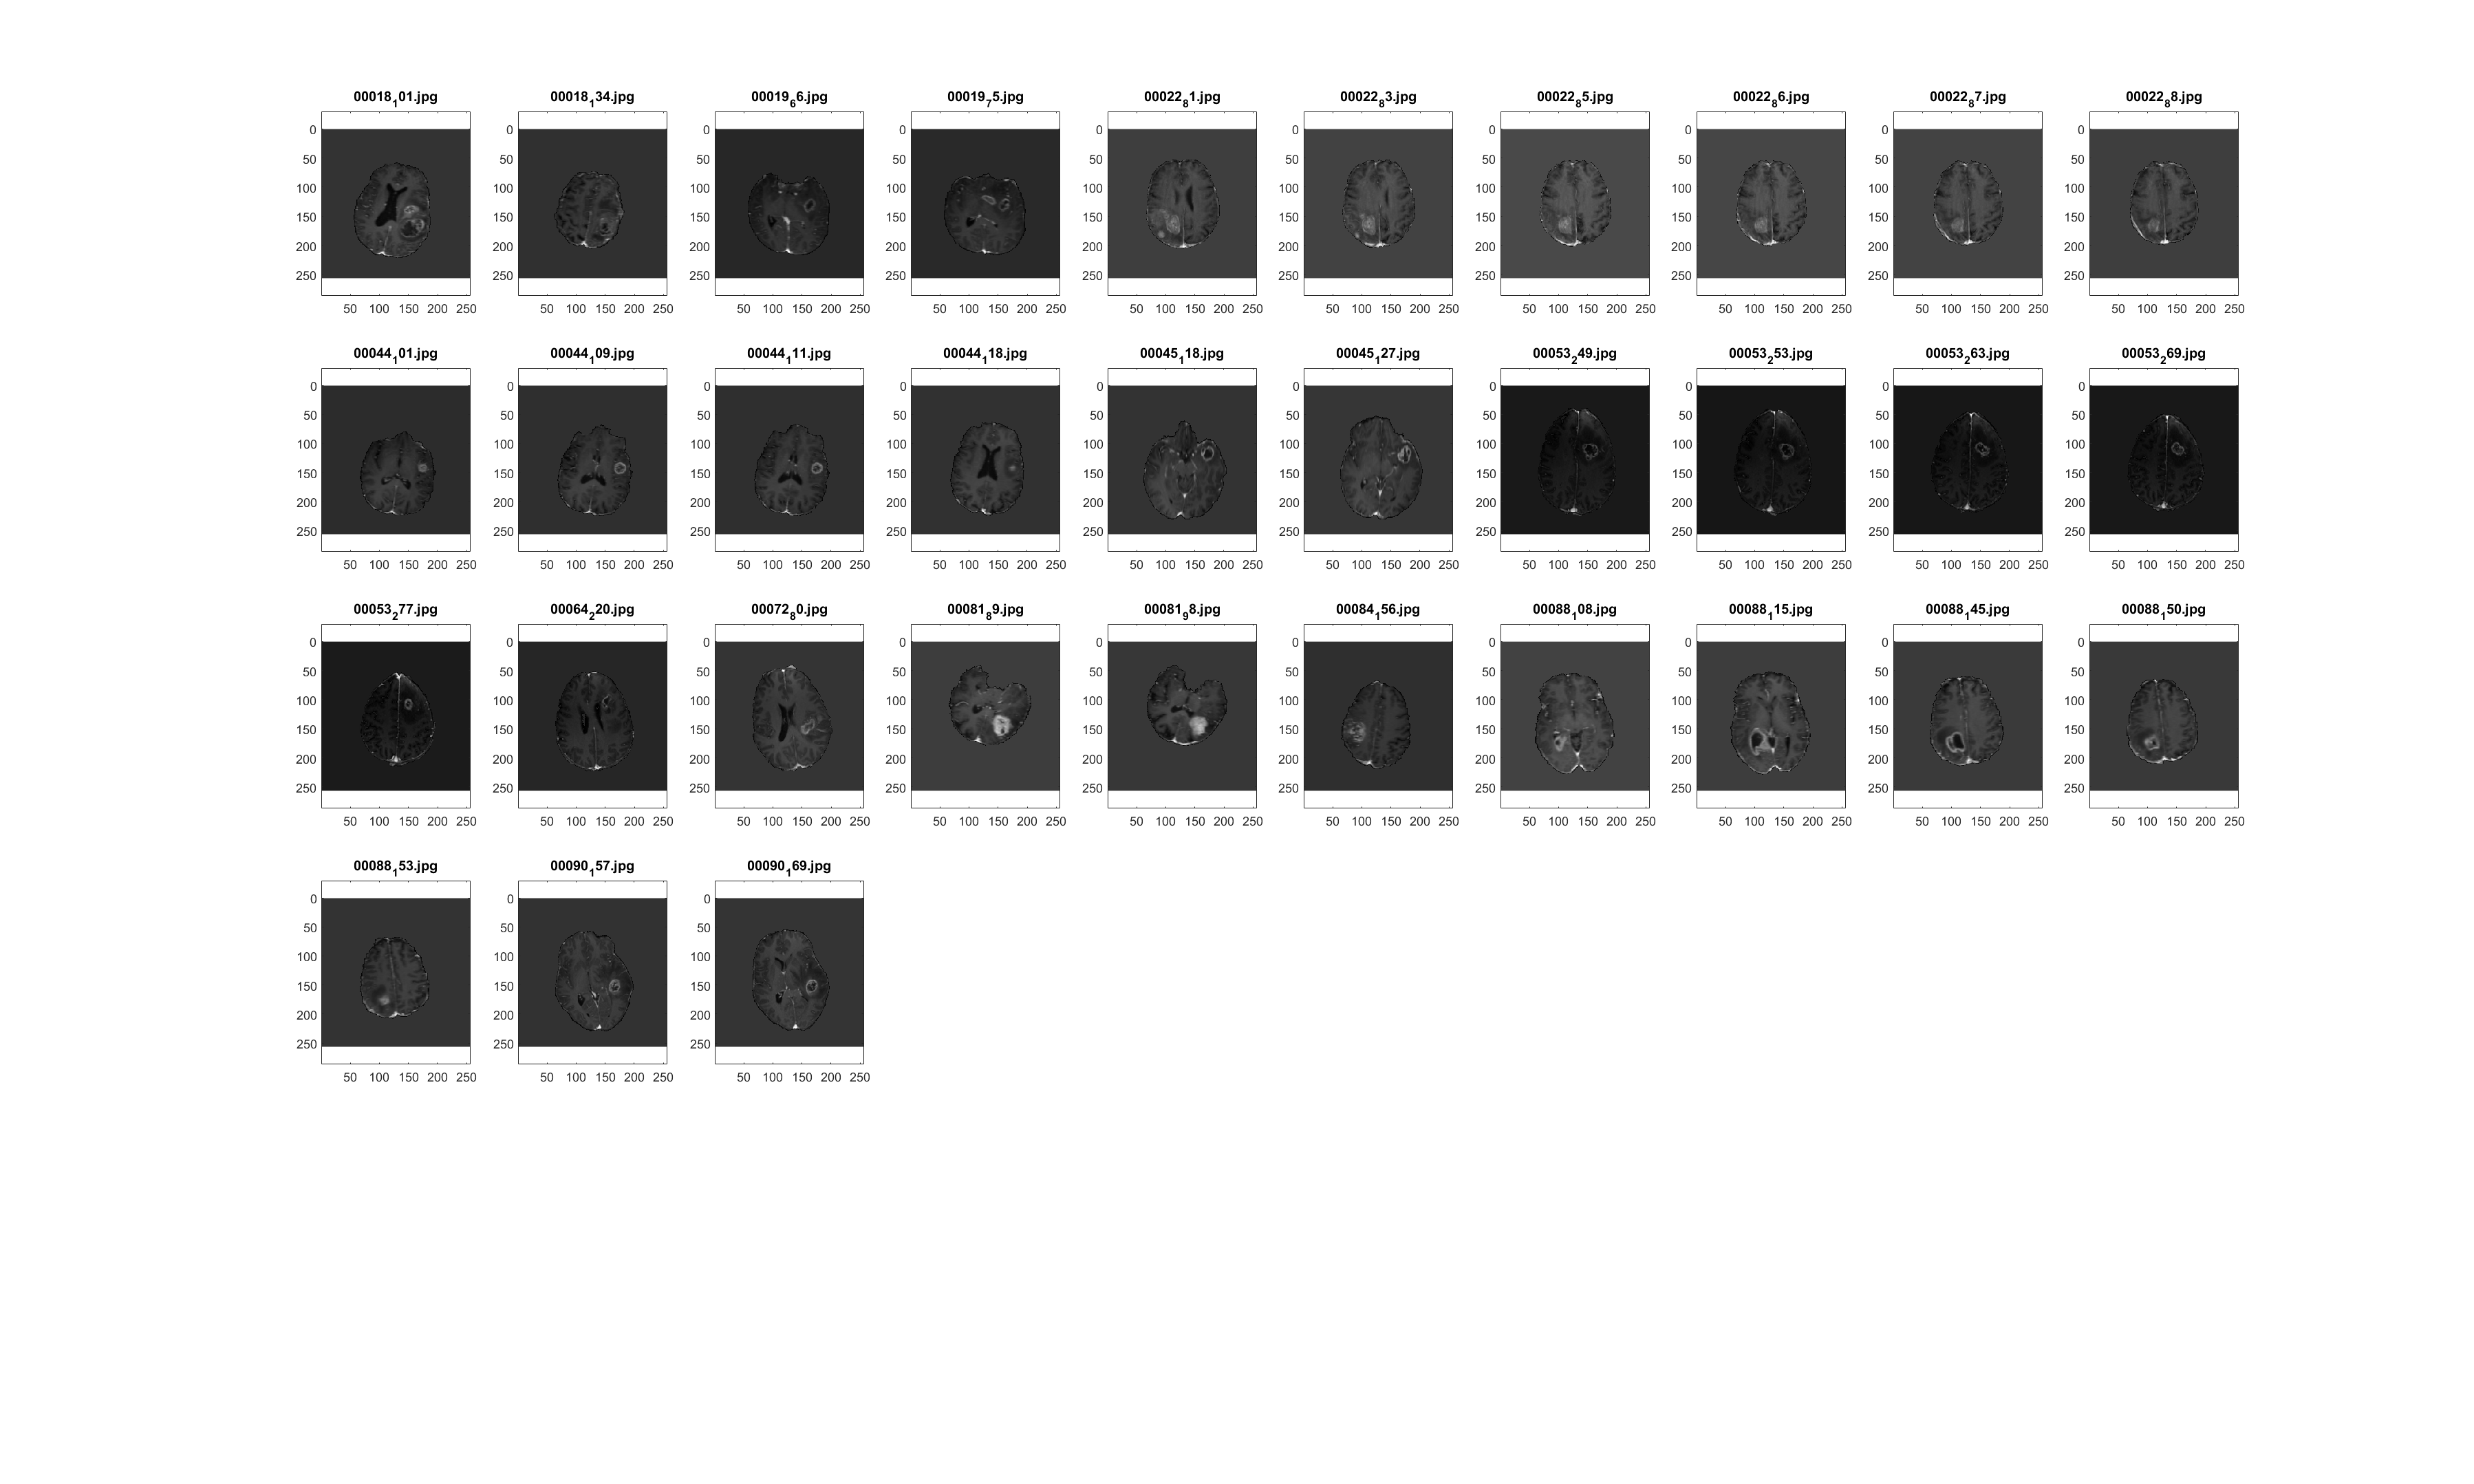

%plot
figure(1)
clf
set(figure(1), "Position", [0 0 5000 3000])
 for i=1:33
     subplot(5,10,i)
     imagesc(reshape(test(i,:), 256, 256))
     title(test_names{i})
     axis equal
 end
 colormap 'gray'

%PCA
 train_mc = train - mean(train, 2);
 R = train_mc' * train_mc;
 [V, D] = eigs(R, 50);

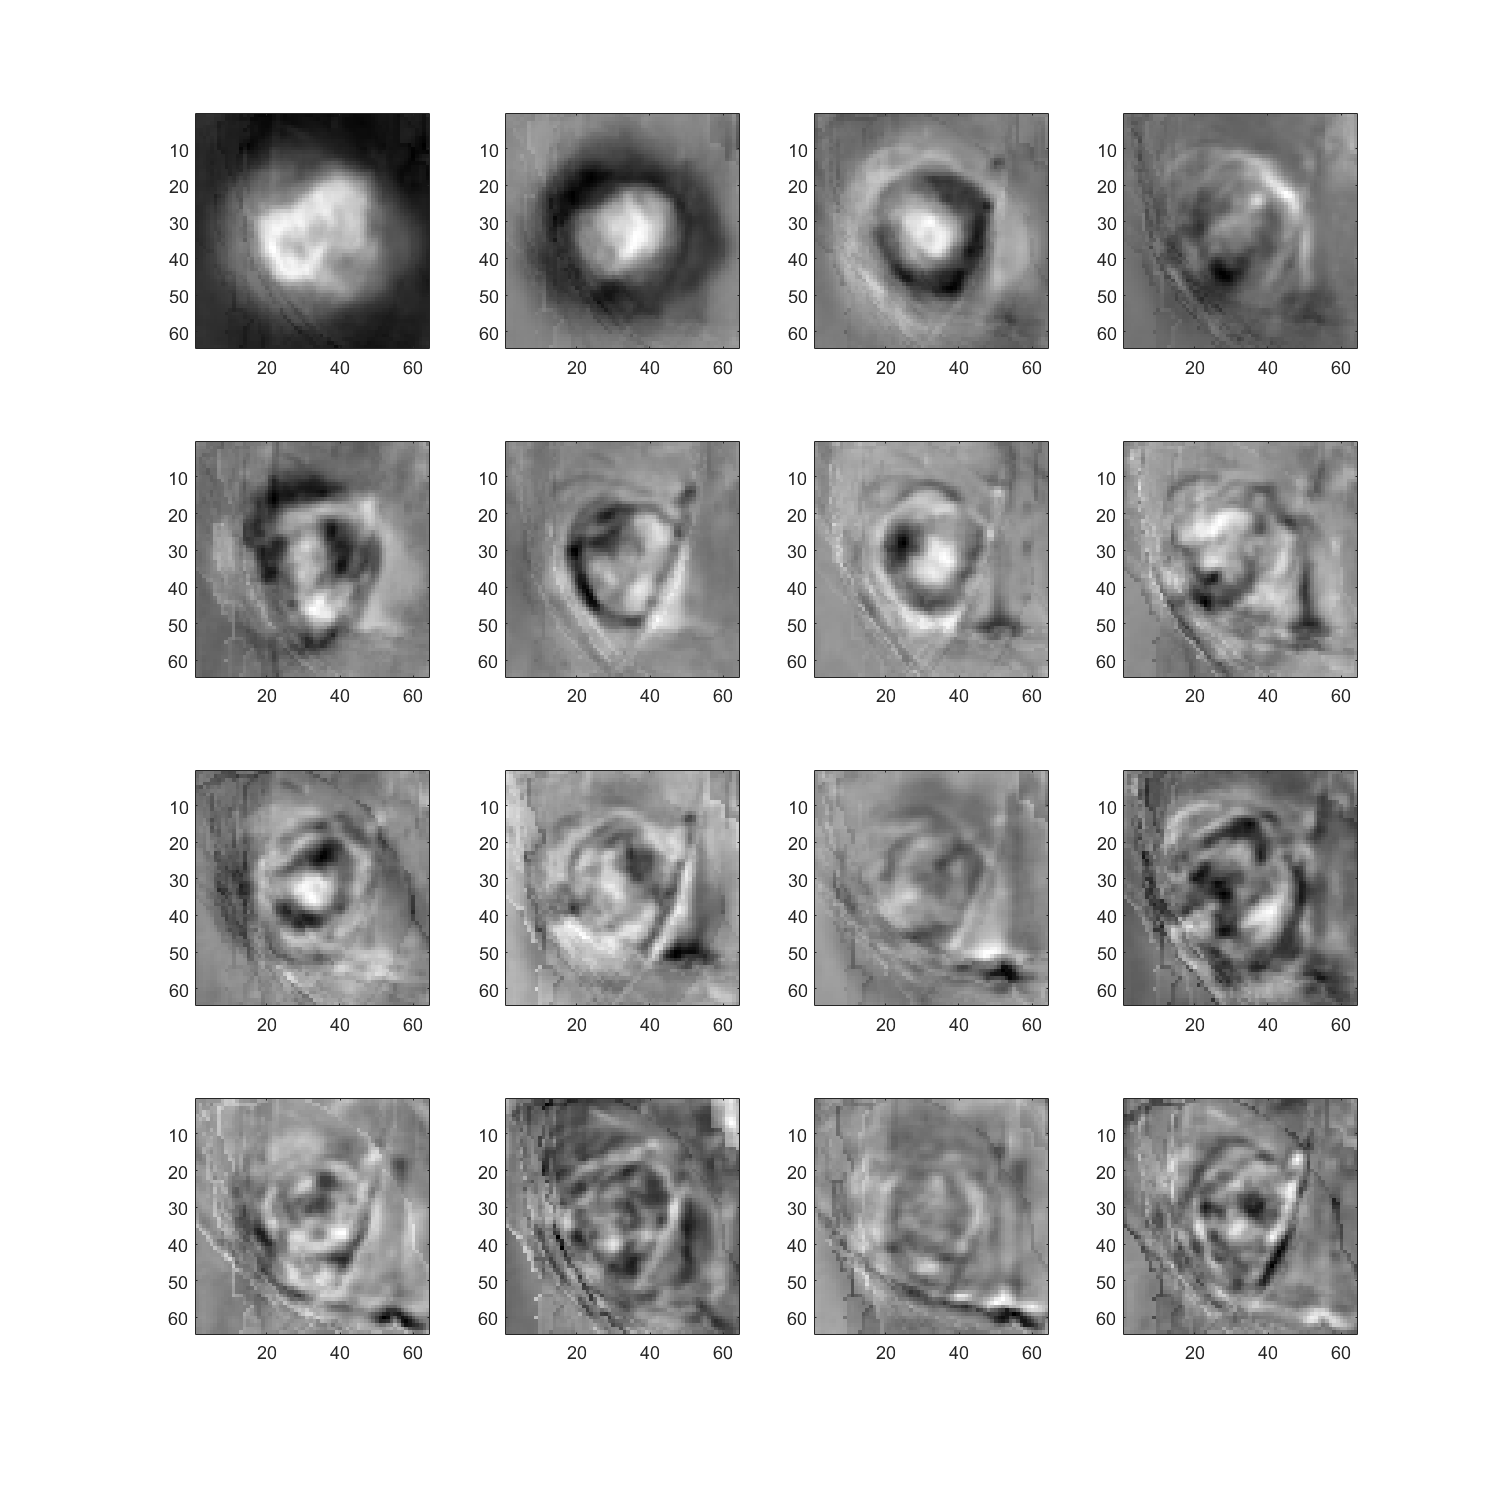

%plot tumor space
 figure(2)
 clf
set(figure(2), "Position", [0 0 1000 1000])
 for i=1:16
     subplot(4,4,i)
     imagesc(reshape(V(:,i), crop_size, crop_size))
     axis equal
 end
 colormap 'gray'

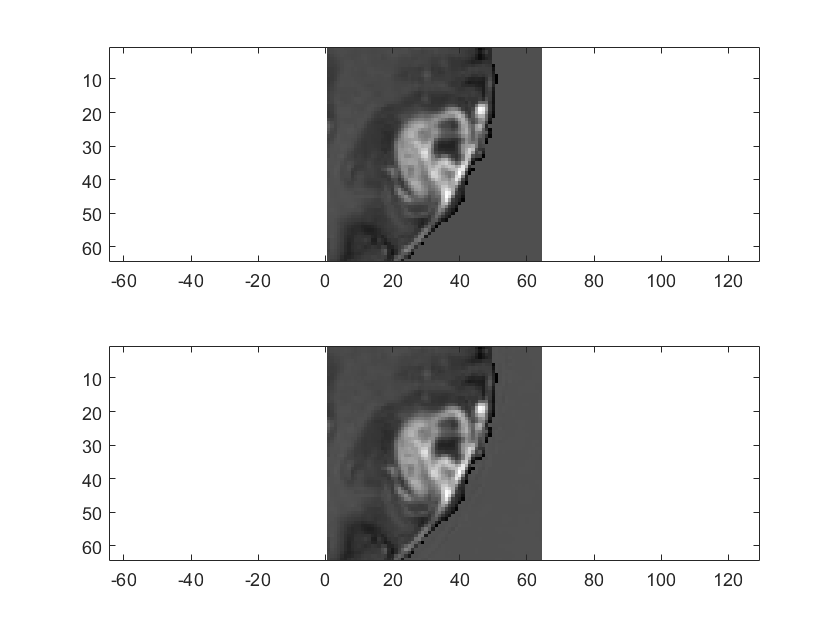


train_comp = train_mc*V;
train_restr = train_comp * V';




i = 12;
figure(3)
clf
subplot(2,1,1)
imagesc(reshape(train_mc(i,:), crop_size, crop_size))
axis equal
subplot(2,1,2)
imagesc(reshape(train_restr(i,:), crop_size, crop_size))
colormap 'gray'
axis equal


norm(train_mc(i,:) - train_restr(i,:))

ans = 37.1946

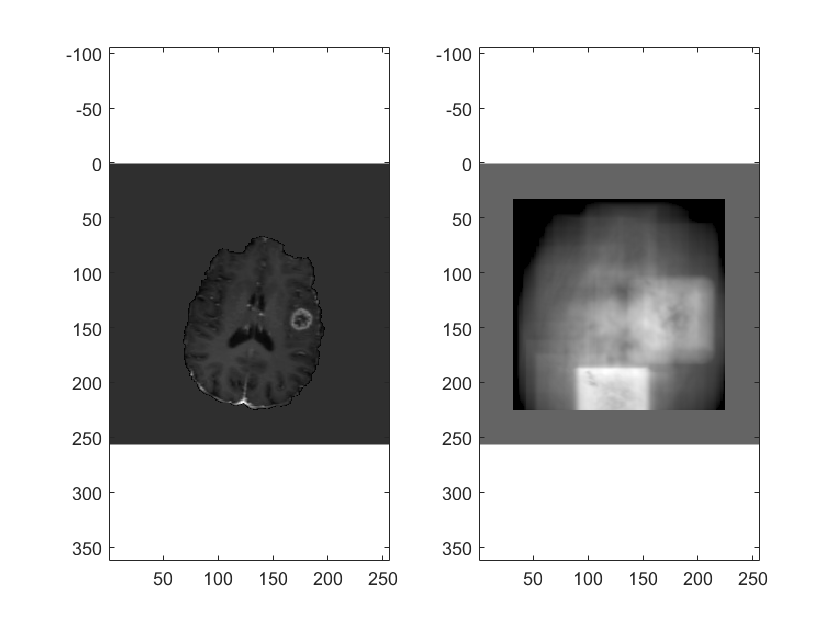

heat_map = zeros(256-crop_size, 256-crop_size);

k = 13;
wholeimage = test(k,:);
wholeimage = reshape(wholeimage, 256, 256);

 
for i=1:256 - crop_size + 1
        for j=1:256 - crop_size + 1

         
        subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        subimage = reshape(subimage, 1, []);
        
        subimage = subimage - mean(subimage);
        
        si_comp = subimage * V;
        si_restr  = si_comp * V';
        
        epsilon = norm(si_restr - subimage);
        heat_map(i, j) = epsilon;
        end
end
heat_map = add_border(heat_map, crop_size);

figure(9)
clf
subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'


[Brightest_Pixel_Value, Max_row, Max_col] = maxpixel(heat_map(50:200, 75:175));
Max_col = Max_col + 74

Max_col = 75

Max_row = Max_row + 49

Max_row = 50

test_labels(k,:) * 256

ans =   175.1736  141.3709


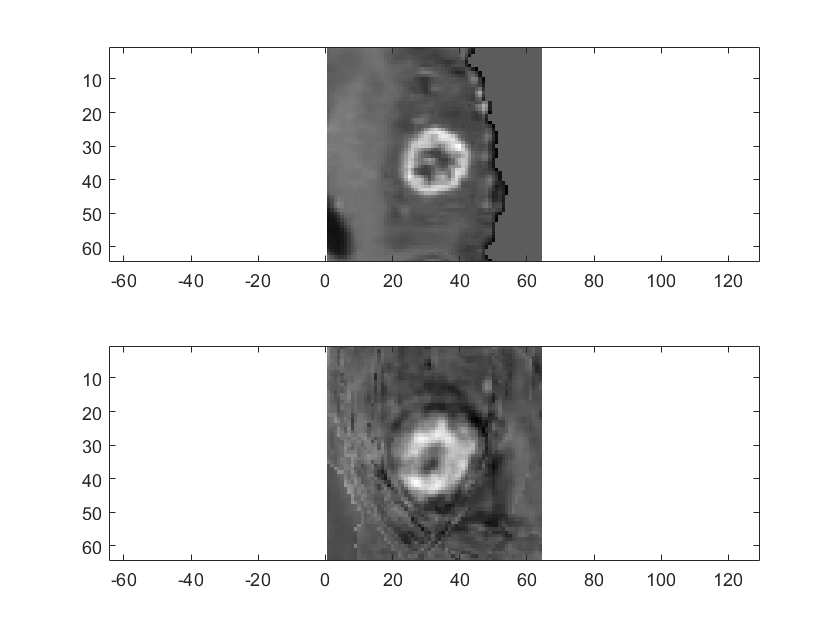

k = 13;
img = test(k,:);
i1 = img < 10;
    i2 = img >= 10;
    img(i1) = mean(img(i2));
    img = img- mean(img);
img = crop_img(reshape(img, 256, 256), test_labels(k,:), crop_size);
img = reshape(img, 1, []);


img_comp = img * V;
img_res = img_comp * V';




figure(5)
clf
subplot(2,1,1)
imagesc(reshape(img, crop_size, crop_size))
axis equal
subplot(2,1,2)
imagesc(reshape(img_res, crop_size, crop_size))
colormap 'gray'
axis equal

norm(img-img_res)

ans = 666.7031